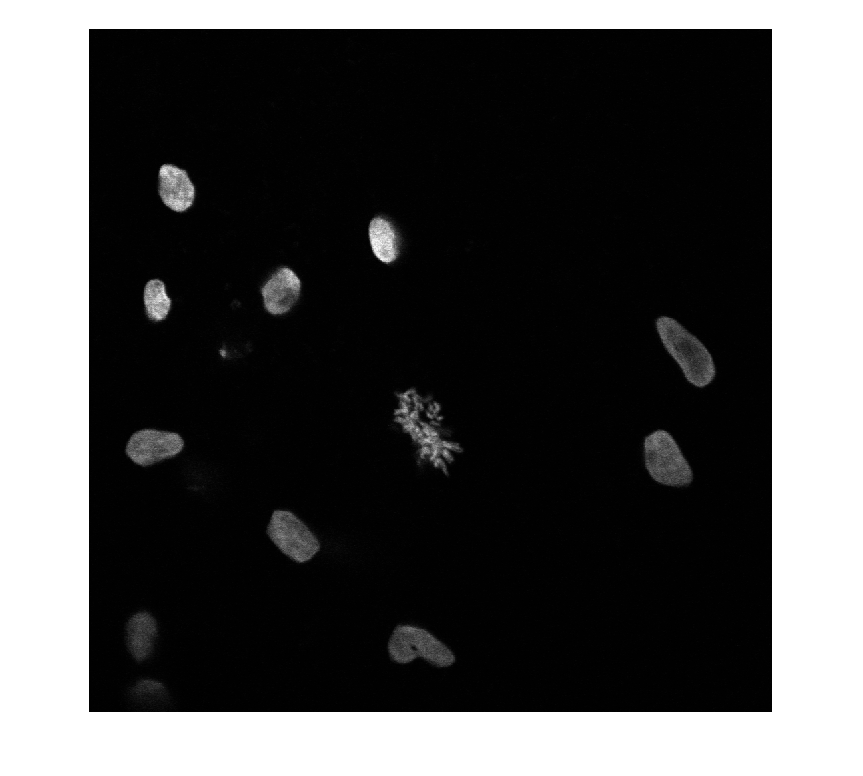

I_blue = imread("Chromosomes-blue.tif") ;
figure ; imshow(I_blue)

**FFT **low pass filter :

F = fftshift(fft2(I_blue));
Fb = F ;

cote = 100 ;
x = size(F, 1) /2;
y = size(F, 2) /2;

for i = 1:size(F, 1)
    for j= 1:size(F, 2)
        if i > x+cote || i < x-cote || j > y+cote || j< y-cote
            Fb(i,j) = 0;
        end
    end
end

rI = ifft2(ifftshift(Fb));

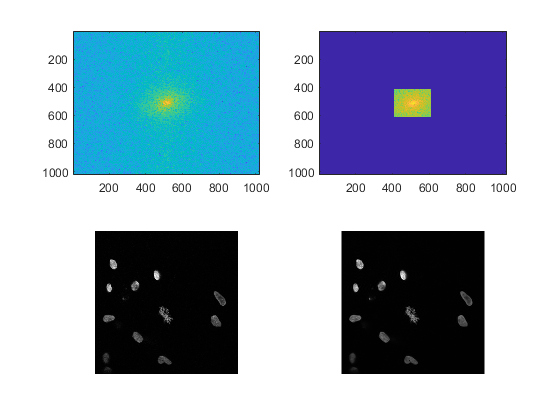

figure ;
subplot(2,2,1); imagesc(log(1+abs(F)));
subplot(2,2,2); imagesc(log(1+abs(Fb)));
subplot(2,2,3); imshow(I_blue);
subplot(2,2,4); imshow(uint16(real(rI)));

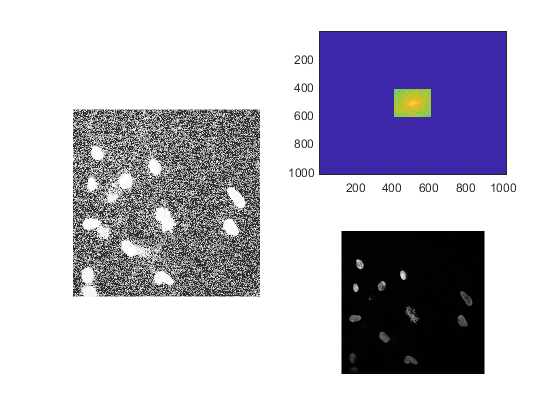

I_blue_eq = histeq(I_blue);
I_blue_eq_med = medfilt2(I_blue_eq, [30 30]);
subplot(1,2,1); imshow(I_blue_eq);

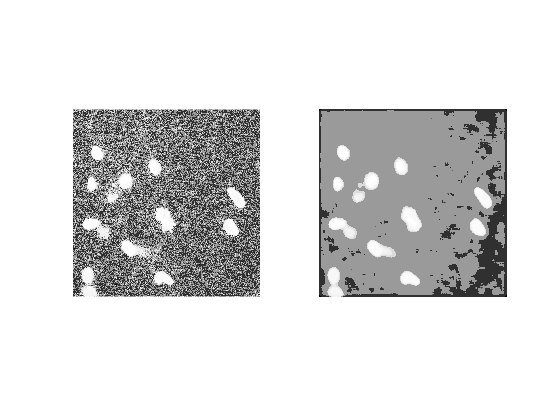

subplot(1,2,2); imshow(I_blue_eq_med);

**Threshold ** : method 1 with histogram equalization + median filter + manual threshold.

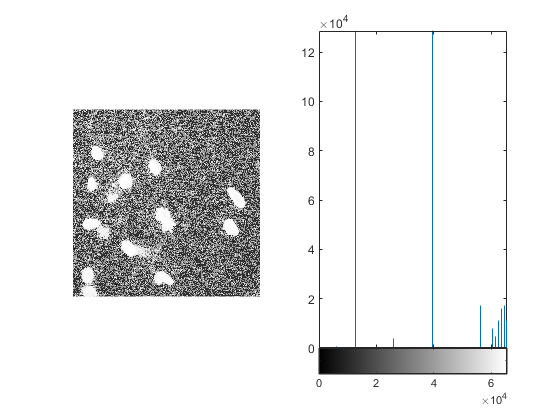

imhist(I_blue_eq_med)

I_blue_threshold1 = I_blue_eq_med ;
I_blue_threshold1(I_blue_threshold1 > 6.2*10^4) = 2^16 ;
I_blue_threshold1(I_blue_threshold1 <= 6.2*10^4) = 0 ;

**Threshold** : method 2 only manual threshold.

I_blue_threshold2 = I_blue;
I_blue_threshold2(I_blue_threshold2 > 5000) = 2^16 ;
I_blue_threshold2(I_blue_threshold2 <= 5000) = 0 ;

**Threshold** : method 3 Otsu.

[T,EM] = graythresh(I_blue_eq_med);
Iotsu = I_blue_eq_med; 
Iotsu(Iotsu>T*(2^16 -1)) = 2^16 -1;
Iotsu(Iotsu<=T*(2^16 -1)) = 0;
Iotsu_blue = logical(Iotsu);

**Comparisons :**

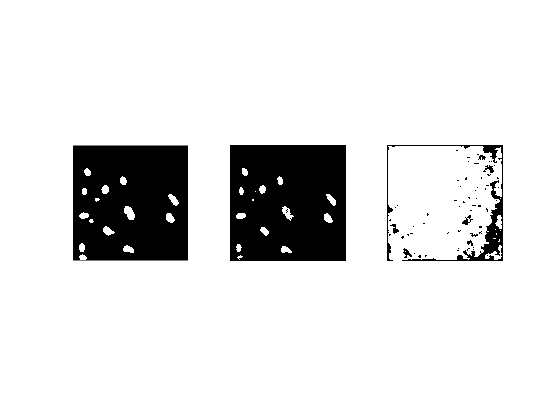

figure ;
subplot(1,3,1); imshow(logical(I_blue_threshold1));
subplot(1,3,2); imshow(logical(I_blue_threshold2));
subplot(1,3,3); imshow(logical(Iotsu_blue));

**Watershed** : detect cells positions.

map = bwdist(I_blue_threshold1);
L = watershed(map);
disp = labeloverlay(I_blue, L);
zones = max(unique(L));

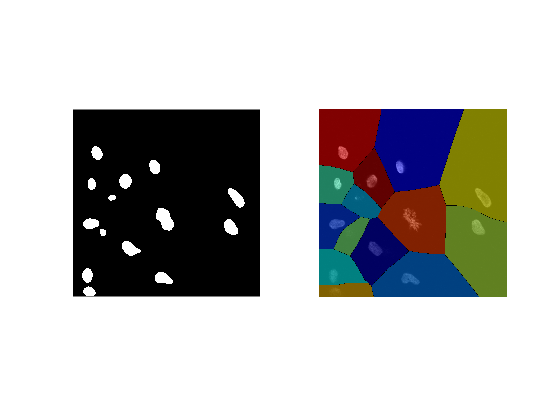

figure ;
subplot(1,2,1); imshow(logical(I_blue_threshold1));
subplot(1,2,2); imshow(disp);

**Crop** the cells from the image:

cells_blue = cell(zones, 1) ;
coord = zeros(2,2,zones) ;

for z=1:zones  
    [r1, c1] = find(L==z);
    wsregion = zeros(max(r1)-min(r1)+1, max(c1)-min(c1)+1);
    for i=min(r1):max(r1)
        for j=min(c1):max(c1)
            if L(i,j) == z && I_blue_threshold1(i,j)==2^16-1
                wsregion(i-min(r1)+1,j-min(c1)+1) = 1;
            else 
                wsregion(i-min(r1)+1,j-min(c1)+1) = 0;
            end
        end
    end
    wsregion = logical(wsregion);
    [r2, c2] = find(wsregion==1);
    % attention au changement de base / d'indice avec la matrice wsregion (+min(r1)-1 ; +min(c1)-1) :
    coord(:, :, z) = [min(r2)+min(r1)-1 max(r2)+min(r1)-1 ; min(c2)+min(c1)-1 max(c2)+min(c1)-1];
    wsregion = wsregion(min(r2):max(r2), min(c2):max(c2)) ;
    cells_blue{z} = wsregion ;
    display(z)
    clear r1 r2 c1 c2 ;
end

z = uint8
   1

z = uint8
   2

z = uint8
   3

z = uint8
   4

z = uint8
   5

z = uint8
   6

z = uint8
   7

z = uint8
   8

z = uint8
   9

z = uint8
   10

z = uint8
   11

z = uint8
   12

z = uint8
   13

z = uint8
   14

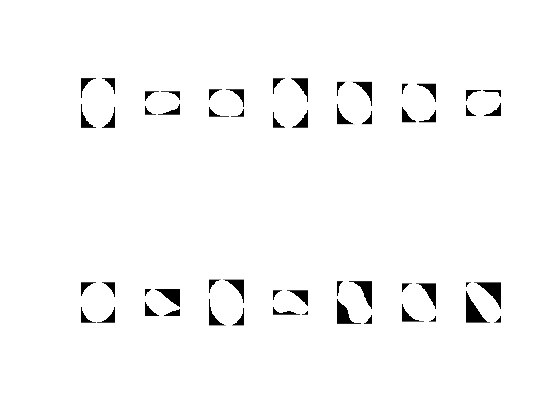

% Plot the cells from blue image
figure ;
for plotId=1:double(zones)
    subplot(2, 7, plotId); 
    imshow(cells_blue{plotId}) ;
end

I_green treatment :

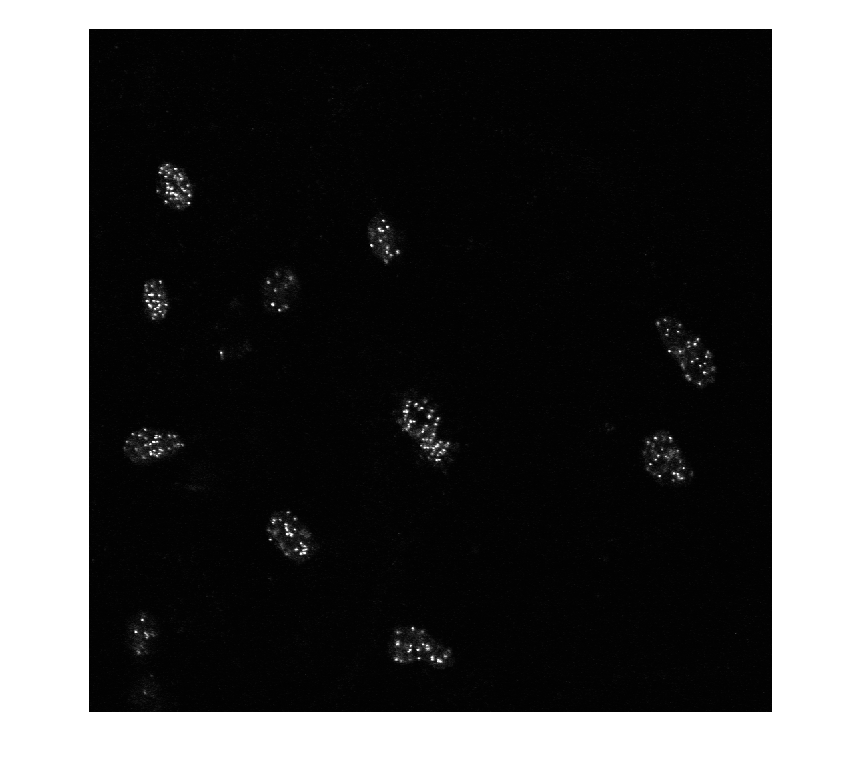

I_green = imread("Chromosomes-green.tif") ;
figure ; imshow(I_green) ;

% imhist(I_green)

**Crop** I_green according to regions extracted from I_blue

cells_green = cell(zones, 1);
for z=1:size(coord,3)
    xmin = coord(1,1,z);
    xmax = coord(1,2,z);
    ymin = coord(2,1,z);
    ymax = coord(2,2,z);
    cells_green{z} = I_green(xmin:xmax, ymin:ymax);
    clear xmin xmax ymin ymax
end

% Plot the cells from green image
display("Plot the cells from green image")

    "Plot the cells from green image"


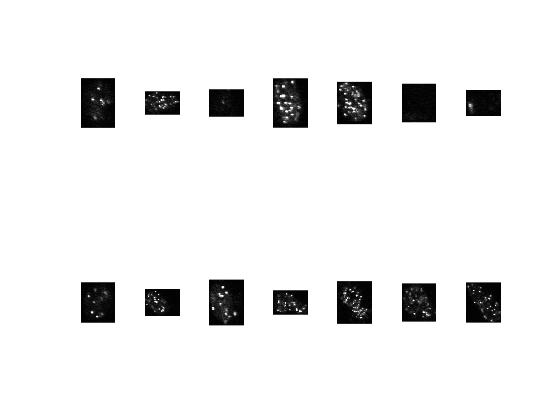

figure ;
for plotId=1:double(zones)
    subplot(2, 7, plotId); 
    imshow(cells_green{plotId}) ;
end

**Otsu** on each cropped cell of I_green :

new_cells_green = cell(zones,1);
for c=1:zones
    I = cells_green{c};
    [T, ~]=graythresh(I);
    I(I>T*(2^16 -1)) = 2^16 -1;
    I(I<=T*(2^16 -1)) = 0;
    new_cells_green{c} = logical(I);
    clear I T
end

% Plot the thresholded cells from green image
display("Plot the thresholded cells from green image")

    "Plot the thresholded cells from green image"


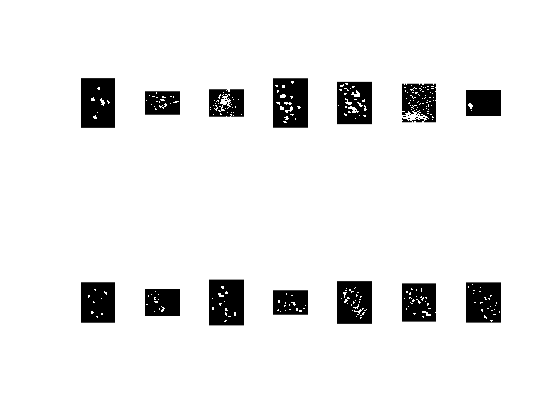

figure ;
for plotId=1:double(zones)
    subplot(2, 7, plotId); 
    imshow(new_cells_green{plotId}) ;
end

-------------------------------------------------------------------------

#### Essais Adrian : 

**a) sur les cellules individuelles directement avec seuil otsu --> marche le "mieux" ?**

**b) 1)Histeq sur cellules individuelles, + 2) median filtering**

**c) essais sur cellule 14 et 5**

-------------------------------------------------------------------------------

### a) Essai : Watershed par cellule pour compter le nb de chromosomes 

sur seuil Otsu :

Cellule 1 : 9 chromosomes.


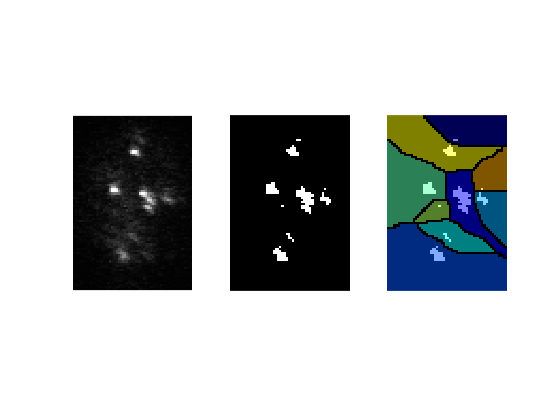

Cellule 2 : 25 chromosomes.


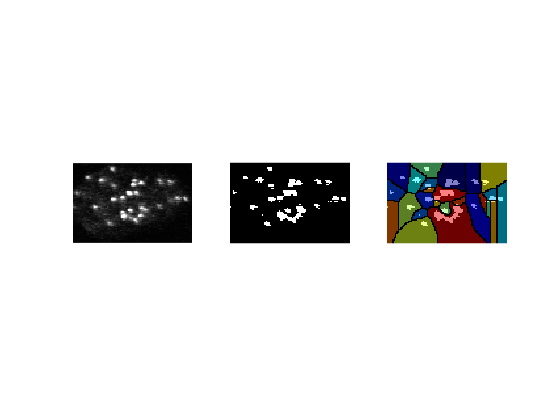

Cellule 3 : 92 chromosomes.


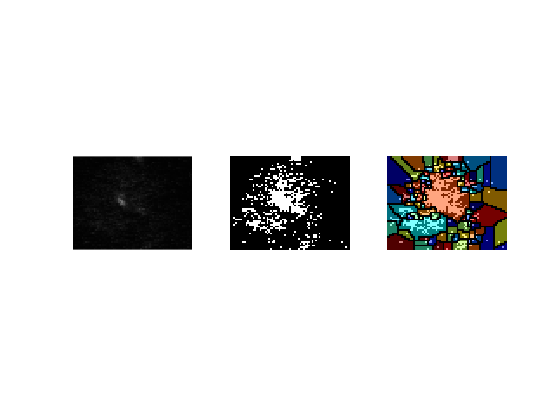

Cellule 4 : 18 chromosomes.


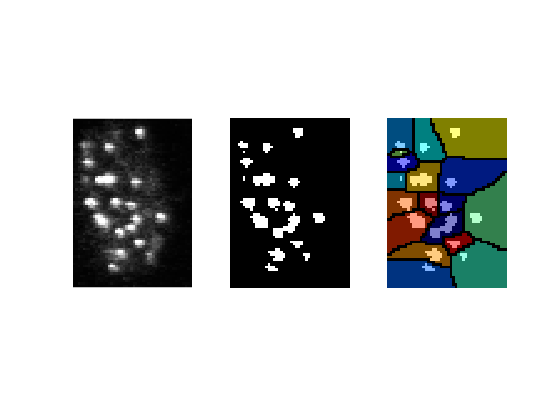

Cellule 5 : 28 chromosomes.


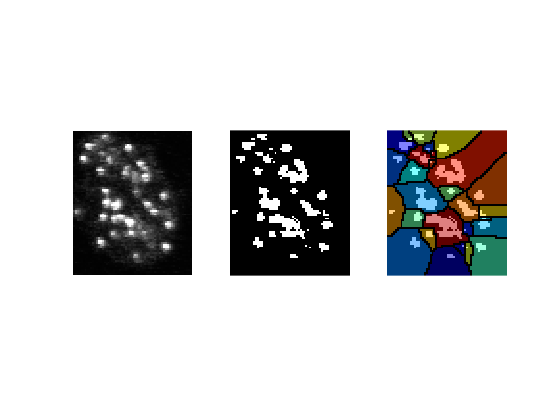

Cellule 

6 : 77 chromosomes.


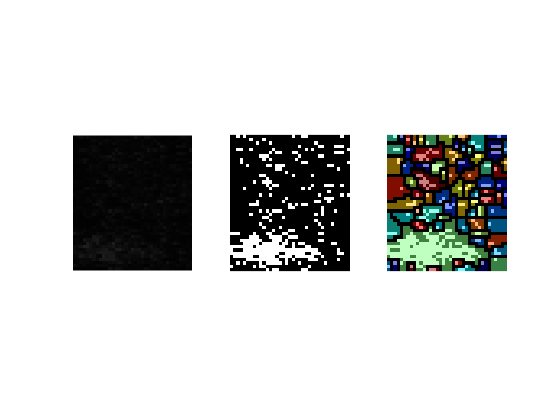

Cellule 7 : 2 chromosomes.


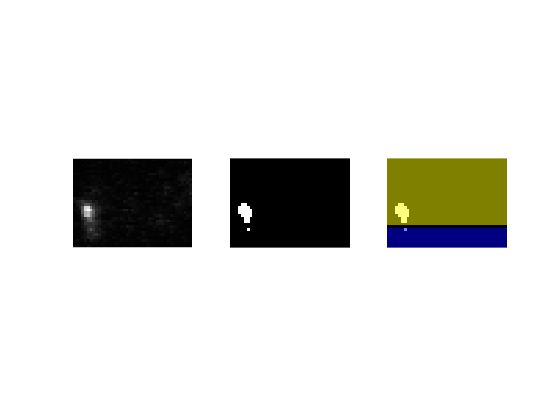

Cellule 8 : 10 chromosomes.


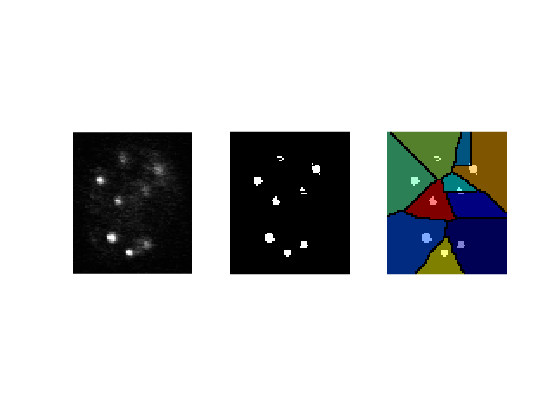

Cellule 9 : 22 chromosomes.


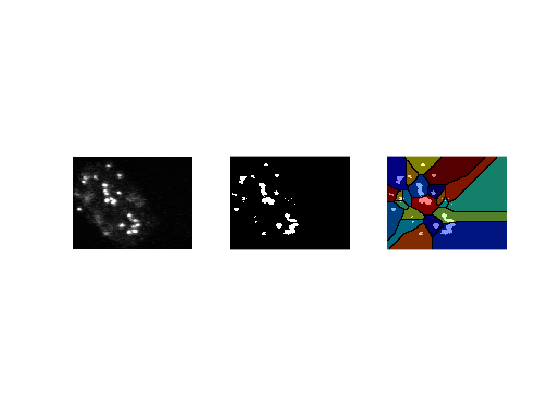

Cellule 10 : 14 chromosomes.


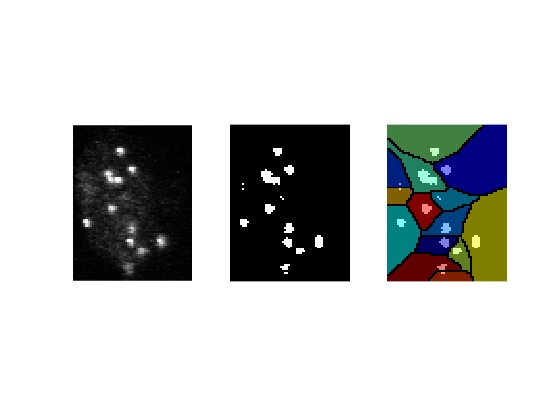

Cellule 11 : 19 chromosomes.


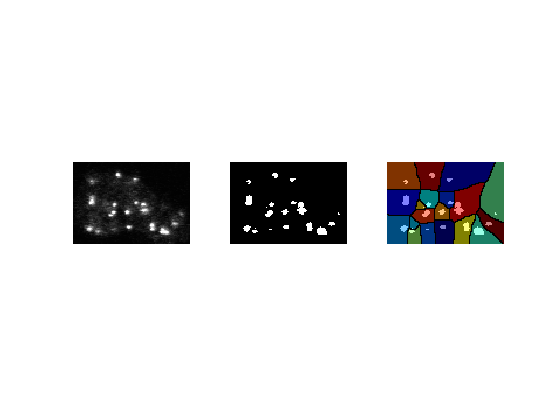

Cellule 12 : 29 chromosomes.


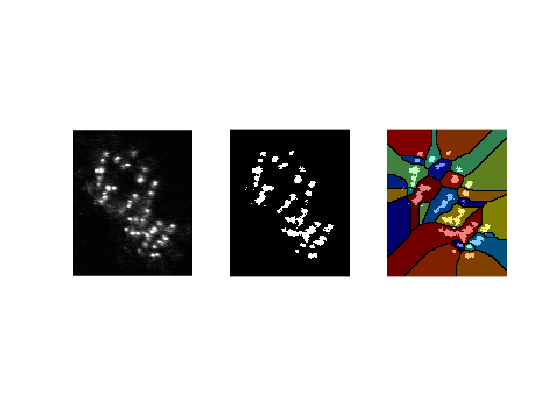

Cellule 13 : 36 chromosomes.


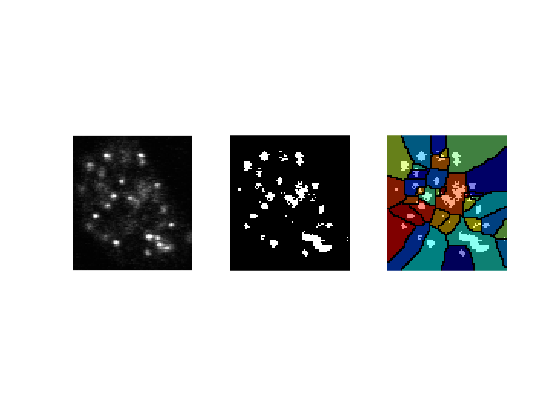

Cellule 14 : 32 chromosomes.


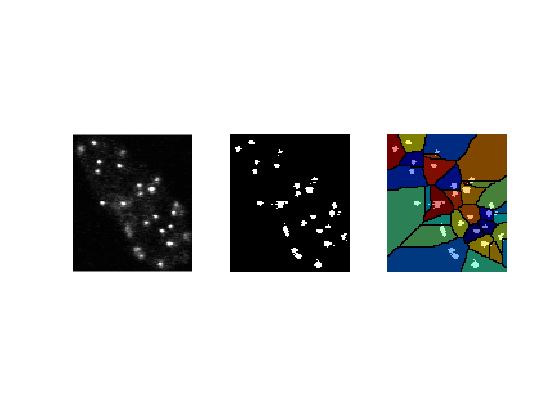

nb_chromosomes = zeros(1,zones);

for plotId=1:double(zones)
    
    %fait le water shed
    map_cell_by_cell_green = bwdist(new_cells_green{plotId}, "quasi-euclidean");
    L = watershed(map_cell_by_cell_green);
    disp_cell = labeloverlay(single(new_cells_green{plotId}), L);
    zones_cell = max(unique(L));
    
    fprintf("Cellule %d : %d chromosomes.\n", plotId, zones_cell)
    %stocke nb cellules
    nb_chromosomes(plotId) = zones_cell;
    figure ;
    subplot(1,3,1); imshow((cells_green{plotId}));
    subplot(1,3,2); imshow(logical(new_cells_green{plotId}));
    subplot(1,3,3); imshow(disp_cell);
end

fprintf(" WATERSHED SUR CELLULES SANS TRAITEMENT \n")

 WATERSHED SUR CELLULES SANS TRAITEMENT 


fprintf("Nombre de cellules détectées : %.f \n", length(nb_chromosomes))

Nombre de cellules détectées : 14 


fprintf("Nombre moyen de chromosomes détectés : %.2f \n", mean(nb_chromosomes))

Nombre moyen de chromosomes détectés : 29.50 


fprintf("Nombre median de chromosomes détectés : %.2f \n", median(nb_chromosomes))

Nombre median de chromosomes détectés : 23.50 


### b) **Histeq sur cellules individuelles, + median filtering**

#### HISTEQ on individual cells :

new_cells_green_eq = cell(zones,1);
% Plot the cells from green image
display("Plot the cells from green image HISTEQ")
figure ;
for plotId=1:double(zones)
    new_cells_green_eq{plotId} = histeq((cells_green{plotId}));
    subplot(2, 7, plotId); 
    imshow(new_cells_green_eq{plotId}) ;
end

#### HISTEQ+MED :

new_cells_green_eq_med = cell(zones,1);
% Plot the cells from green image
display("Plot the cells from green image HISTEQ+MED")
figure ;
med_filter = 4;
for plotId=1:double(zones)
    new_cells_green_eq_med{plotId} = medfilt2(new_cells_green_eq{plotId}, [med_filter med_filter]);
    subplot(2, 7, plotId); 
    imshow(new_cells_green_eq_med{plotId}) ;
end

### b1) Essai : Watershed sur HISTEQ par cellule pour compter le nb de chromosomes + 

Seuil à la main

nb_chromosomes_eq = zeros(1,zones);
fprintf("--------------\n HISTEQ \n--------------\n")

--------------
 HISTEQ 
--------------


Cellule 1 : 5 chromosomes.


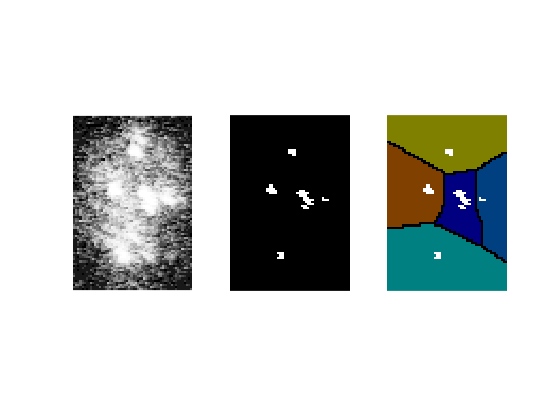

Cellule 

2 : 21 chromosomes.


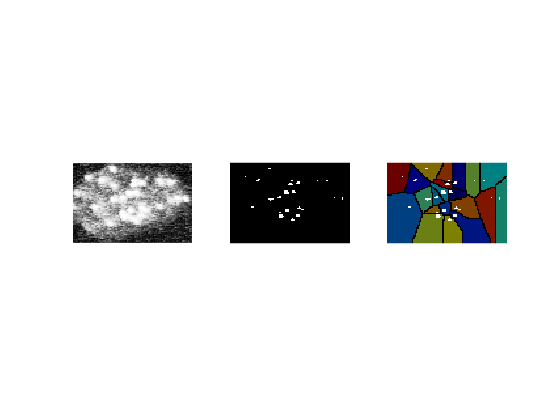

Cellule 3 : 11 chromosomes.


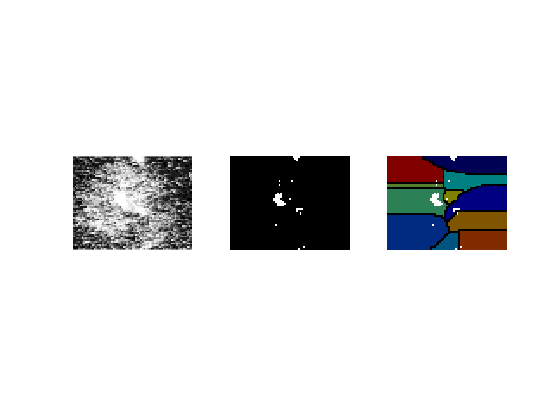

Cellule 4 : 16 chromosomes.


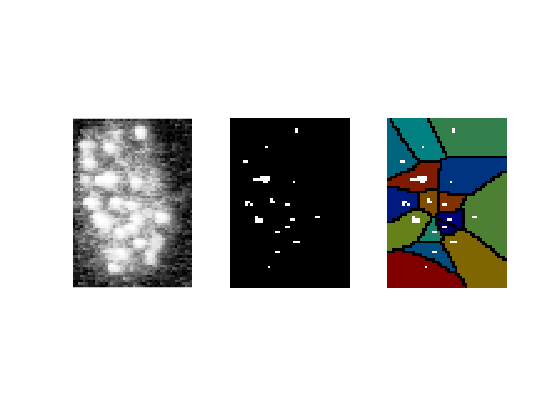

Cellule 5 : 20 chromosomes.


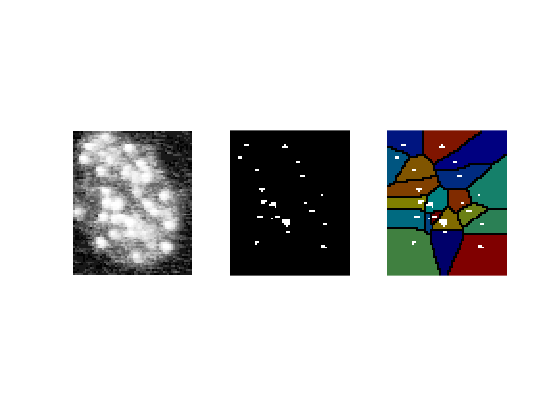

Cellule 6 : 10 chromosomes.


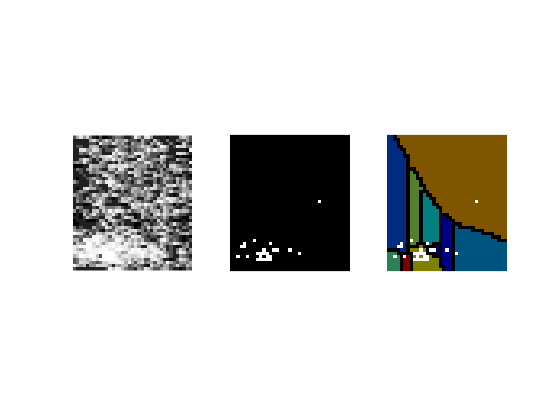

Cellule 7 : 1 chromosomes.


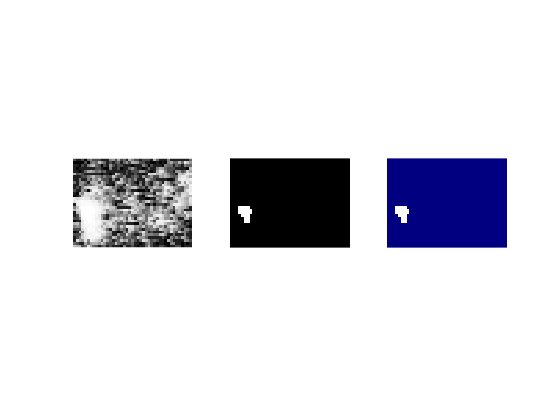

Cellule 8 : 8 chromosomes.


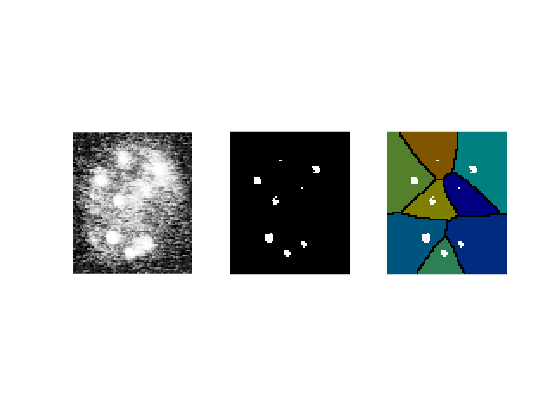

Cellule 9 : 15 chromosomes.


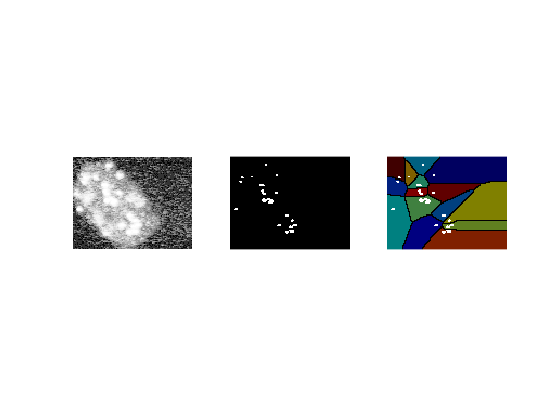

Cellule 10 : 9 chromosomes.


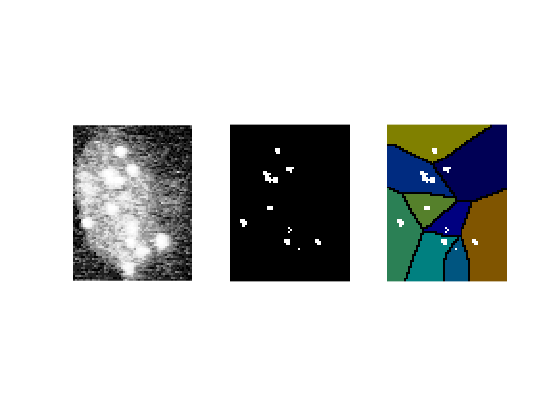

Cellule 11 : 17 chromosomes.


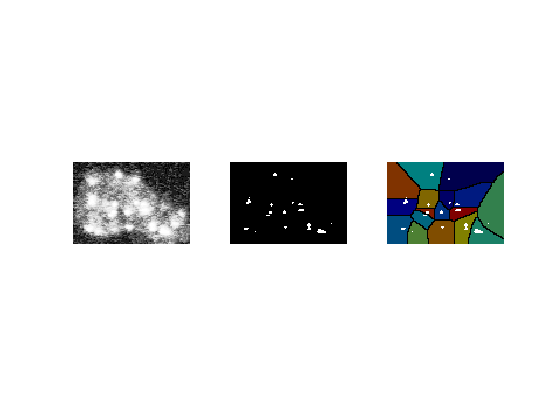

Cellule 12 : 32 chromosomes.


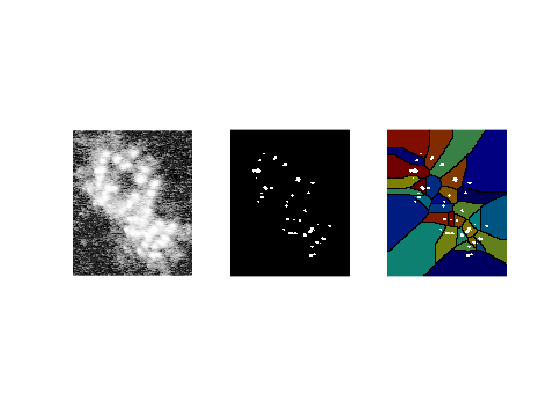

Cellule 13 : 19 chromosomes.


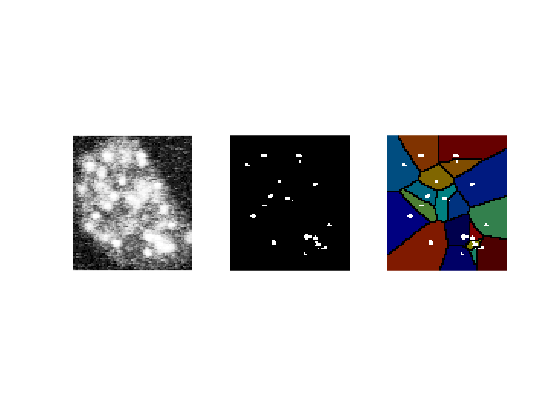

Cellule 14 : 25 chromosomes.


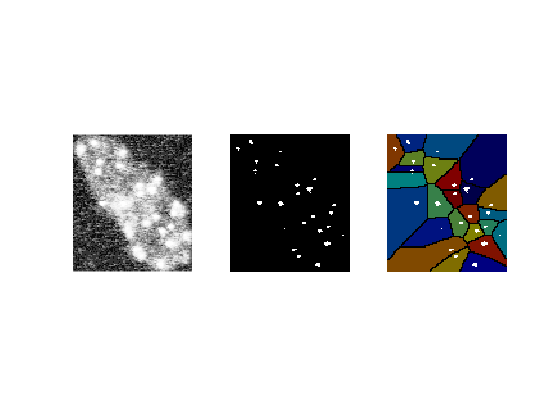

for plotId=1:double(zones)
    
    %seuil main : 
    treshold = 6.5*10^4;
    im_tr = new_cells_green_eq{plotId};
    im_tr(im_tr > treshold) = 2^16 ;
    im_tr(im_tr <= treshold) = 0 ;
    
    %fait le water shed
    map_cell_by_cell_green = bwdist(im_tr);
    L = watershed(map_cell_by_cell_green);
    disp_cell_eq = labeloverlay(single(im_tr), L);
    zones_cell = max(unique(L));
    
    fprintf("Cellule %d : %d chromosomes.\n", plotId, zones_cell)
    %stocke nb cellules
    nb_chromosomes_eq(plotId) = zones_cell;
    figure ;
    subplot(1,3,1); imshow(new_cells_green_eq{plotId});
    subplot(1,3,2); imshow(logical(im_tr));
    subplot(1,3,3); imshow(disp_cell_eq);
end

### b2) Essai : Watershed sur HISTEQ+MED par cellule pour compter le nb de chromosomes + 

Seuil à la main

nb_chromosomes_eq_med = zeros(1,zones);
fprintf("--------------\n HISTEQ+MED \n--------------\n")

--------------
 HISTEQ+MED 
--------------


Cellule 1 : 3 chromosomes.


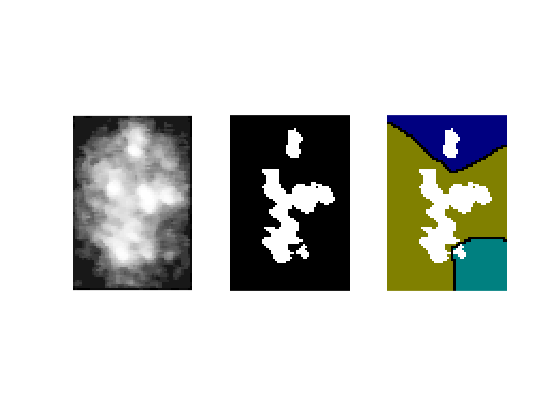

Cellule 

2 : 12 chromosomes.


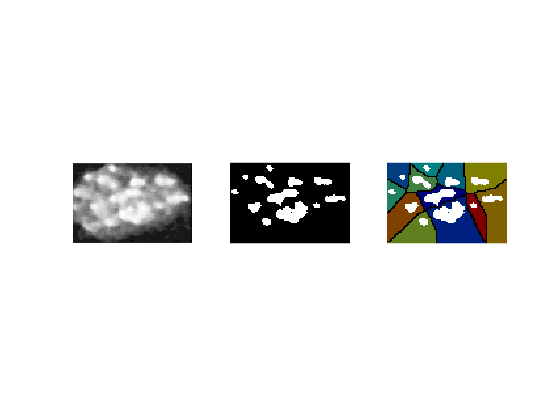

Cellule 3 : 9 chromosomes.


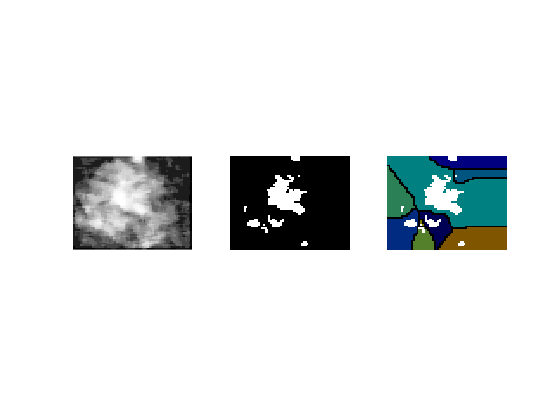

Cellule 4 : 9 chromosomes.


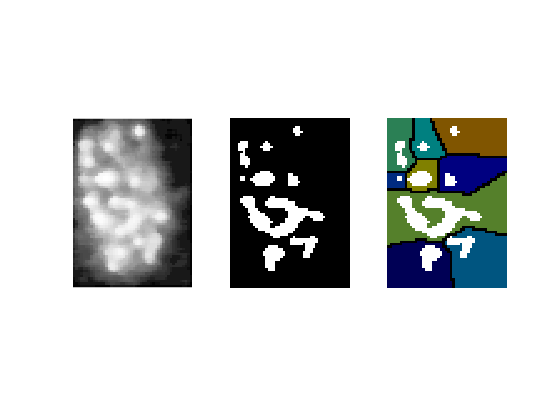

Cellule 5 : 15 chromosomes.


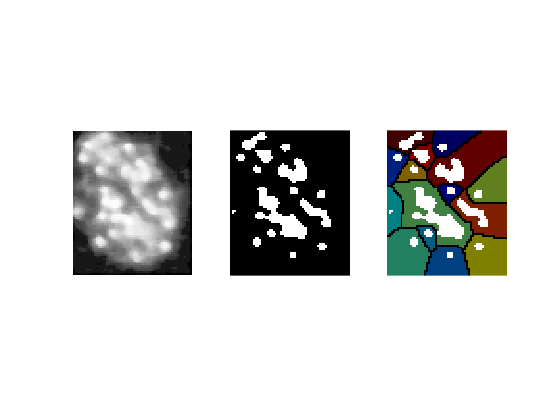

Cellule 6 : 1 chromosomes.


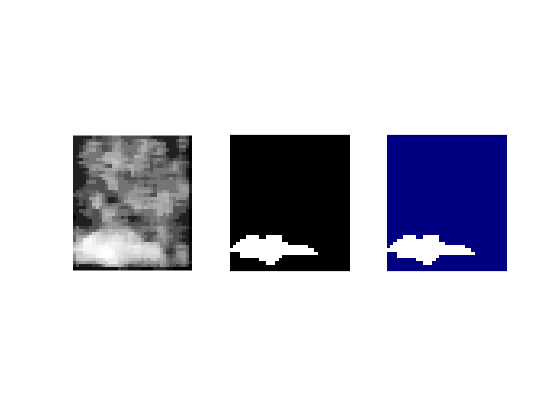

Cellule 7 : 3 chromosomes.


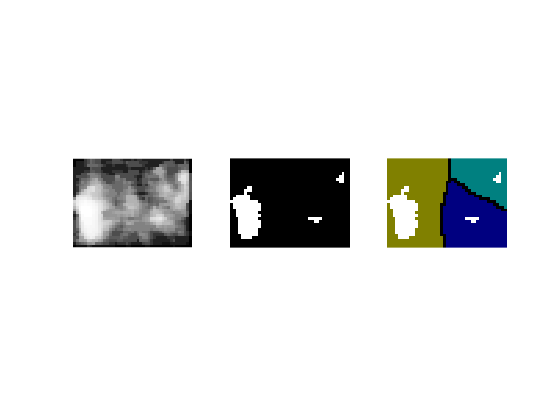

Cellule 8 : 9 chromosomes.


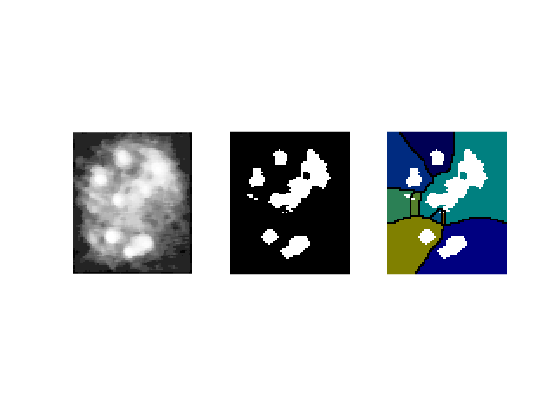

Cellule 9 : 8 chromosomes.


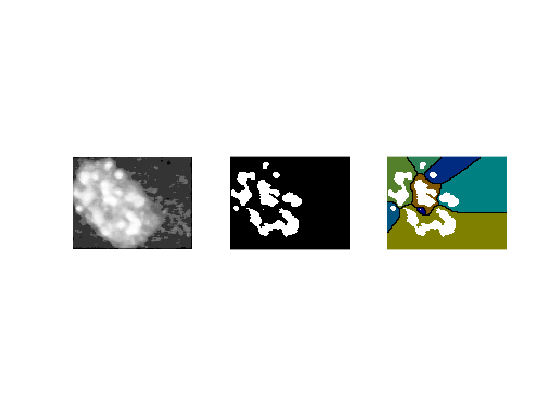

Cellule 10 : 7 chromosomes.


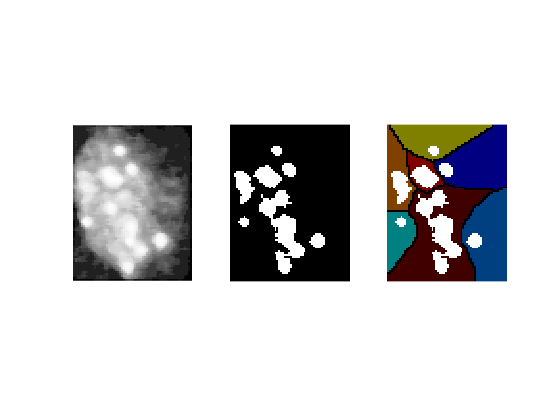

Cellule 11 : 14 chromosomes.


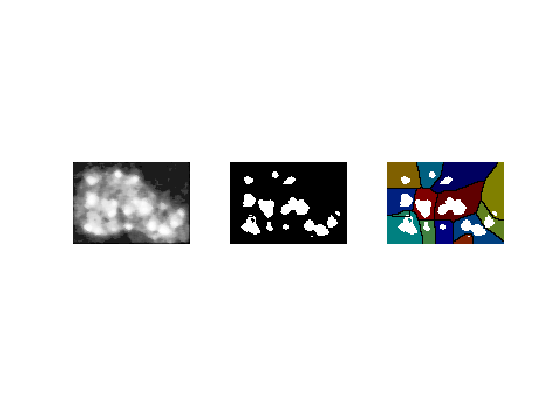

Cellule 12 : 6 chromosomes.


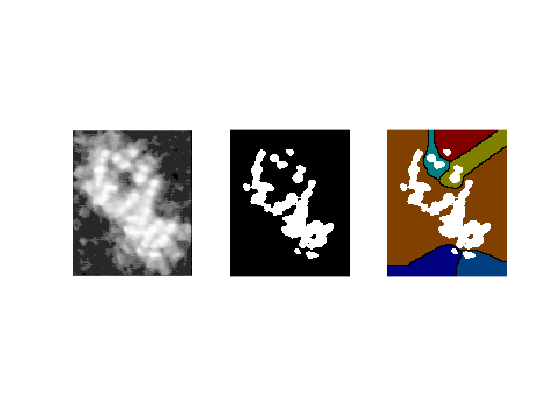

Cellule 13 : 18 chromosomes.


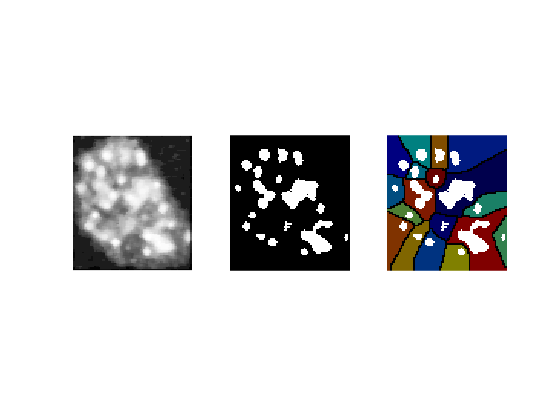

Cellule 14 : 16 chromosomes.


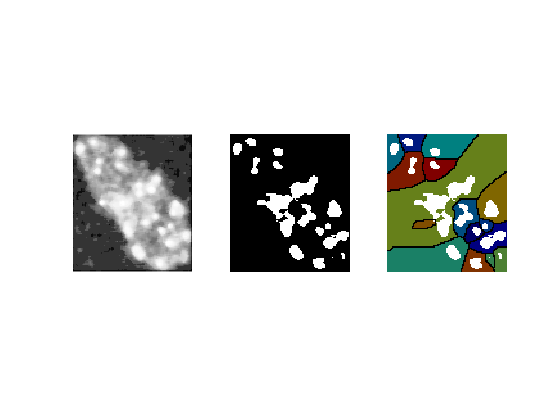

for plotId=1:double(zones)
    
    %seuil main : 
    treshold = 5.5*10^4;
    im_tr = new_cells_green_eq_med{plotId};
    im_tr(im_tr > treshold) = 2^16 ;
    im_tr(im_tr <= treshold) = 0 ;
    
    %fait le water shed
    map_cell_by_cell_green = bwdist(im_tr);
    L = watershed(map_cell_by_cell_green);
    disp_cell_eq_med = labeloverlay(single(im_tr), L);
    zones_cell = max(unique(L));
    
    fprintf("Cellule %d : %d chromosomes.\n", plotId, zones_cell)
    %stocke nb cellules
    nb_chromosomes_eq_med(plotId) = zones_cell;
    figure ;
    subplot(1,3,1); imshow(new_cells_green_eq_med{plotId});
    subplot(1,3,2); imshow(logical(im_tr));
    subplot(1,3,3); imshow(disp_cell_eq_med);
end

## Essai : keskispas sur une cellule isolée (14 et 5)

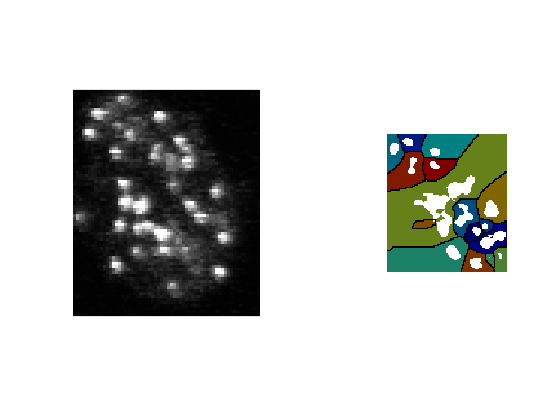

cellule5 = cells_green{5};
cellule14 = cells_green{14};
subplot(1,2,1); imshow(cellule5) ;

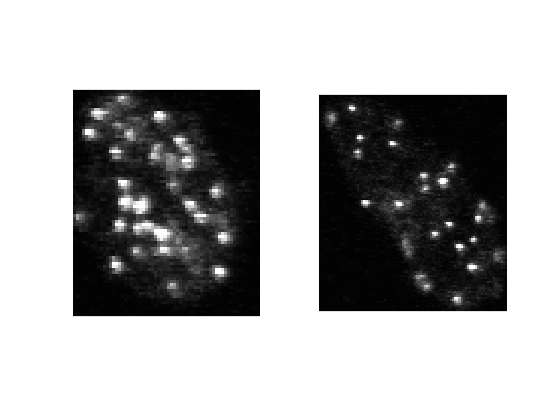

subplot(1,2,2); imshow(cellule14) ;

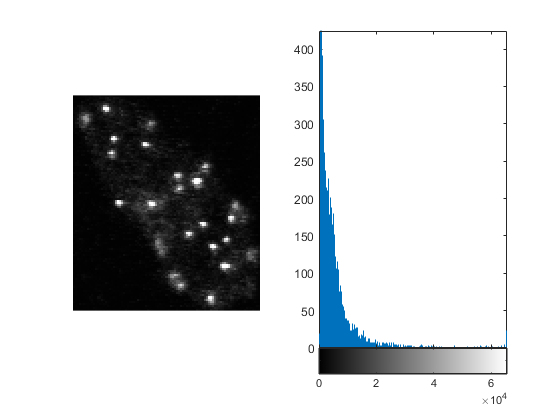

subplot(1,2,1); imshow(cellule14) ;
subplot(1,2,2); imhist(cellule14) ;

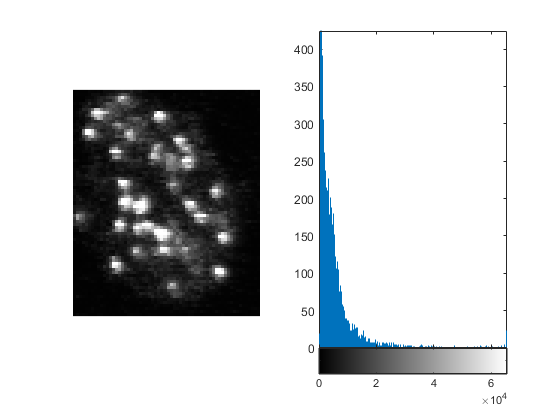

subplot(1,2,1); imshow(cellule5) ;

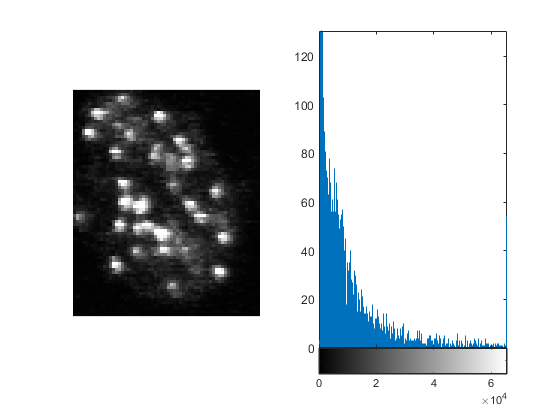

subplot(1,2,2); imhist(cellule5) ;

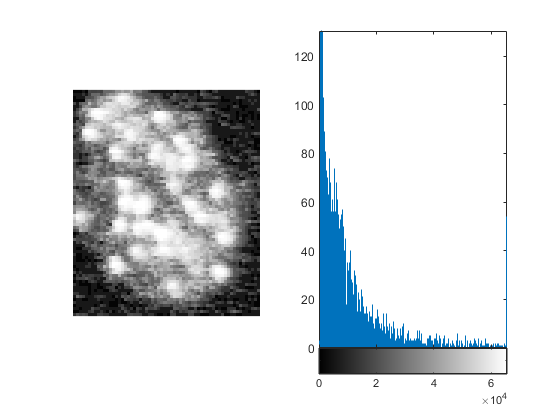

C5_eq = histeq(cellule5);
C5_eq_med = medfilt2(C5_eq, [2 2]);
subplot(1,2,1); imshow(C5_eq);

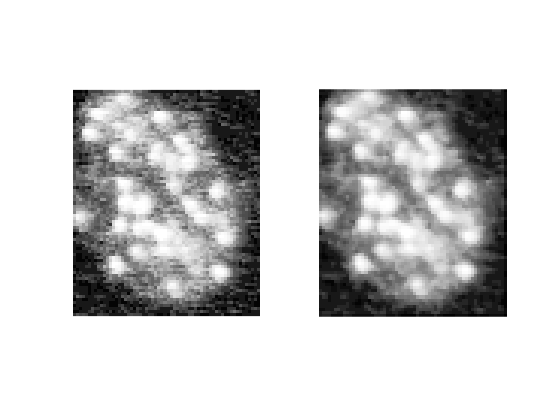

subplot(1,2,2); imshow(C5_eq_med);

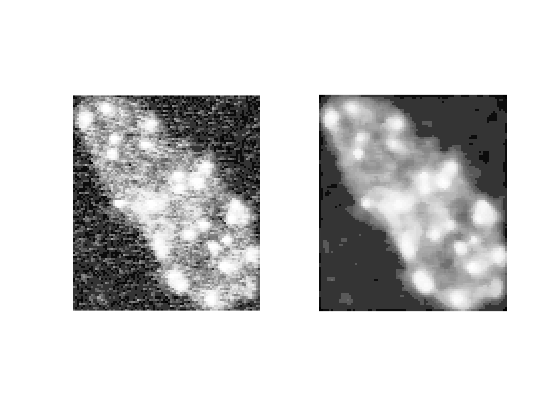

C14_eq = histeq(cellule14);
C14_eq_med = medfilt2(C14_eq, [5 5]);
subplot(1,2,1); imshow(C14_eq);
subplot(1,2,2); imshow(C14_eq_med);

**Threshold ** : method 1 with histogram equalization  + med_filter + manual threshold.

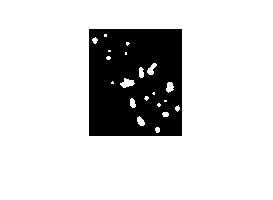

C14_threshold1 = C14_eq_med ;
%threshold
tres = 6.1*10^4;

C14_threshold1(C14_threshold1 > tres) = 2^16 ;
C14_threshold1(C14_threshold1 <= tres) = 0 ;
%figure;imshow(C14_threshold1) ;
%C14_threshold1 = imfill(C14_threshold1, 'holes');
figure; imshow(C14_threshold1);



%watershed
map_cell_by_cell_green = bwdist(C14_threshold1, "quasi-euclidean");
L = watershed(map_cell_by_cell_green);
disp_cell = labeloverlay(single(C14_threshold1), L);
zones_cell = max(unique(L));
fprintf("Cellule 14 : %d chromosomes.\n",  zones_cell)

Cellule 14 : 20 chromosomes.


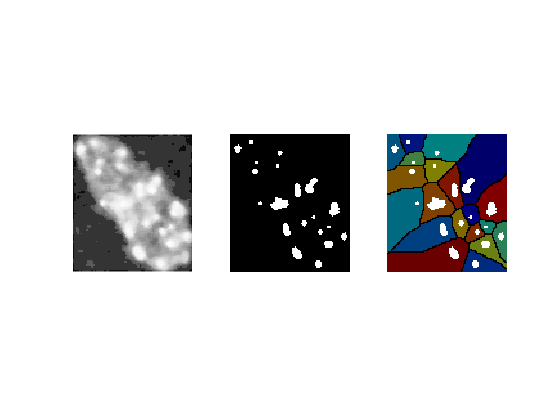


figure ;
subplot(1,3,1); imshow((C14_eq_med));
subplot(1,3,2); imshow((C14_threshold1));
subplot(1,3,3); imshow(disp_cell);

C5_threshold1 = C5_eq_med ;
%threshold
tres = 6.1*10^4;

C5_threshold1(C5_threshold1 > tres) = 2^16 ;
C5_threshold1(C5_threshold1 <= tres) = 0 ;
%watershed
map_cell_by_cell_green = bwdist(C5_threshold1, "quasi-euclidean");
L = watershed(map_cell_by_cell_green);
disp_cell = labeloverlay(single(C5_threshold1), L);
zones_cell = max(unique(L));
fprintf("Cellule 5 : %d chromosomes.\n",  zones_cell)

Cellule 5 : 25 chromosomes.


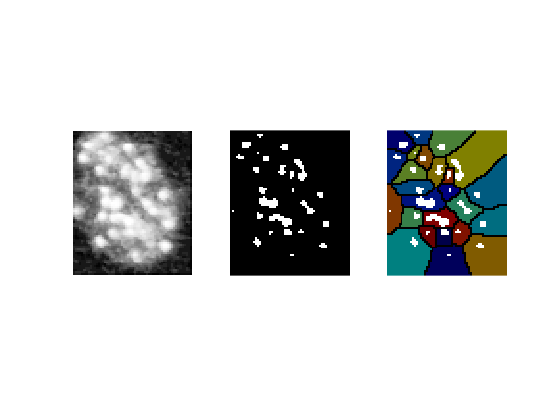


figure ;
subplot(1,3,1); imshow((C5_eq_med));
subplot(1,3,2); imshow(logical(C5_threshold1));
subplot(1,3,3); imshow(disp_cell);